Read an image file to a variable and then display the image:

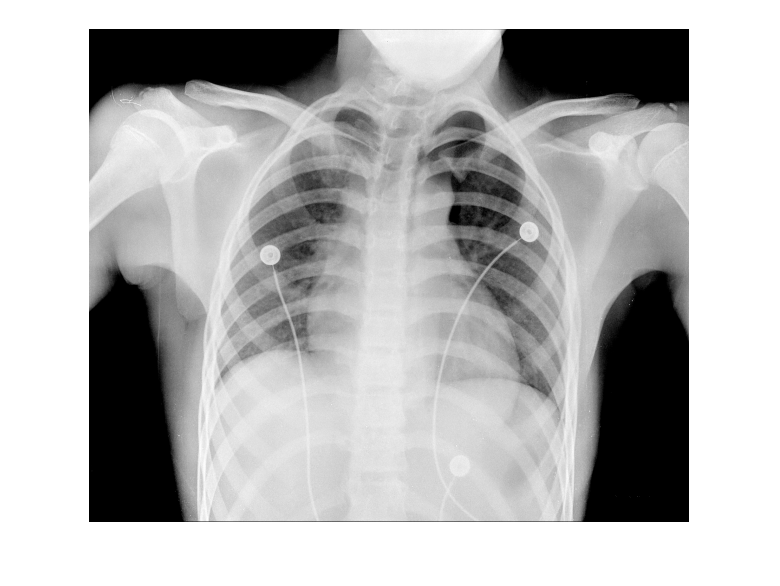

cd 'C:\Users\Roman\Repositories\tutorials\matlab\image_processing';
f = imread('images\chestxray.tif');
imshow(f)

Displaying the next image will replace the first image:

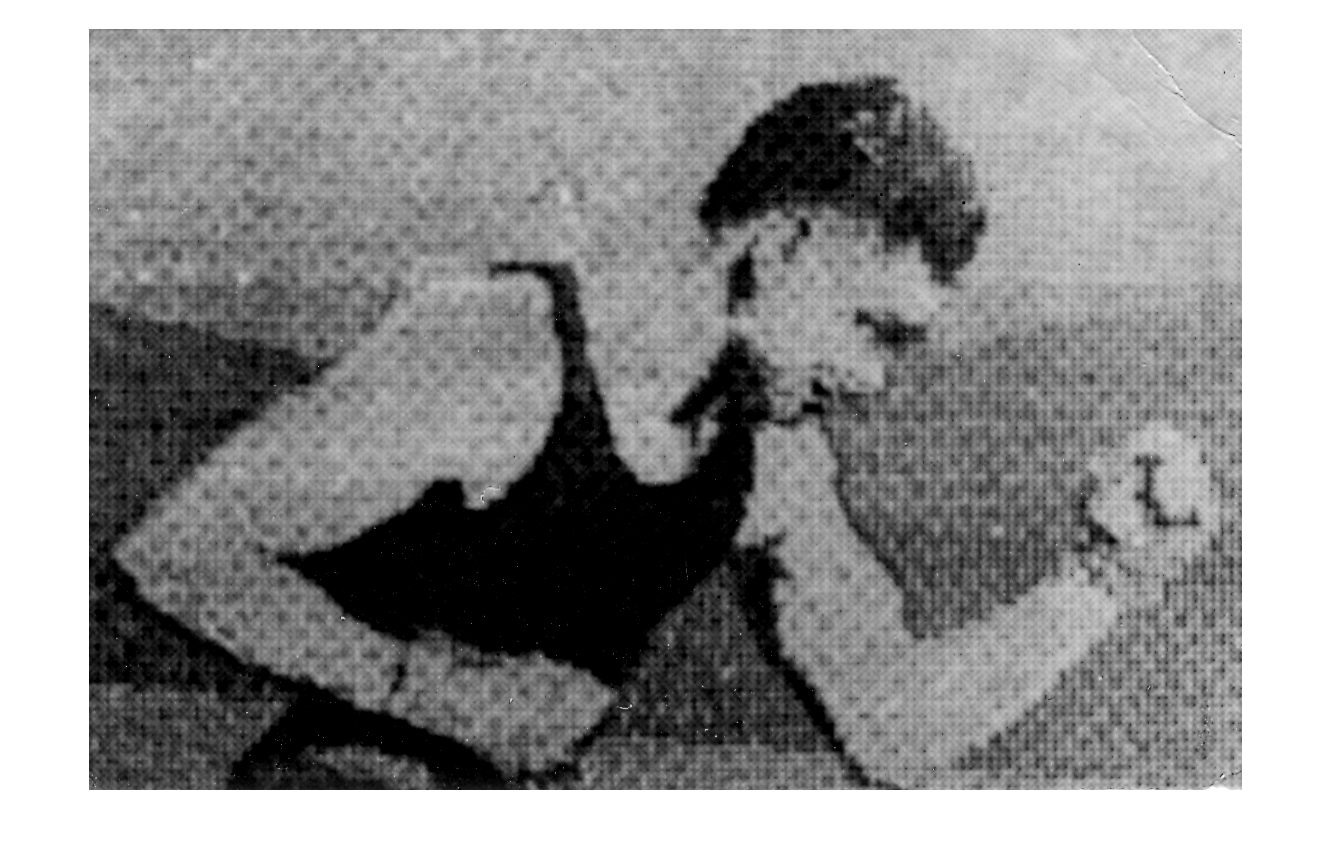

g = imread('images\runner.tif');
imshow(g)

Keep first image open and open a new window with the second image:

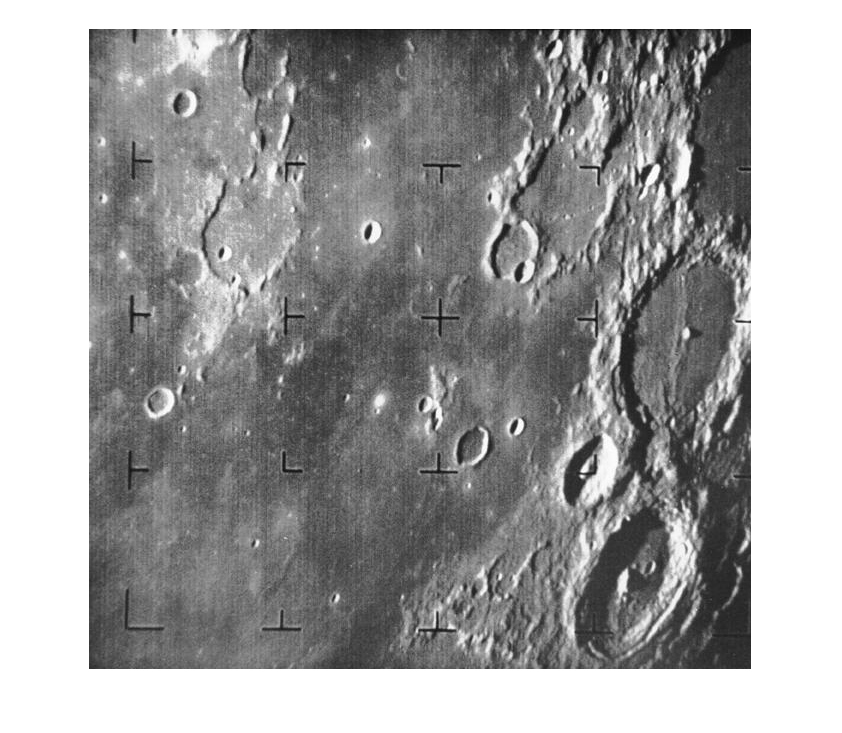

h = imread('images\moon.tif');
figure, imshow(h)

To write images to disk:

imwrite(f,'images\chestxarray.jpg','quality',80);

Convert to binary image with logical function:

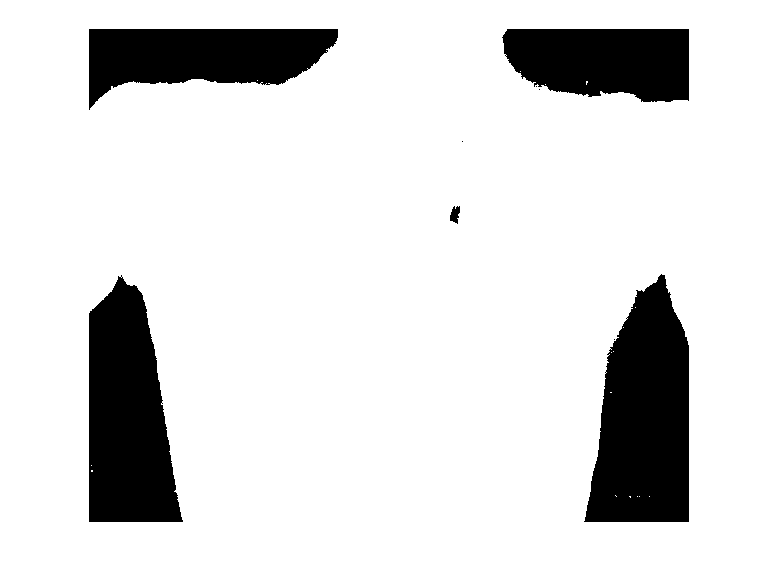

F = logical(f);
imshow(F)

Test for logical array:

islogical(F)

ans = logical
   1


Convert an image to an array of double:

G = mat2gray(g);
imshow(G)

Matrix operations

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


sum(A(:))

ans = 45

D = logical([1 0 0; 0 0 1; 0 0 0])

D = 3×3 logical array
   1   0   0
   0   0   1
   0   0   0


A(D)

ans =      1
     6


(r,c) = can be accessed by single subscript r+M(c-1). For example, A(2,3) = A(8)

A(2,3)

ans = 6

A(8)

ans = 6

Named function handle

f = @sin

f = function_handle with value:
    @sin


f(pi/2)

ans = 1

Anonymous function handle

g = @(x) x.^2;
r = @(x,y) sqrt(x.^2 + y.^2);
g(A)

ans =      1     4     9
    16    25    36
    49    64    81


r(A,D)

ans =     1.4142    2.0000    3.0000
    4.0000    5.0000    6.0828
    7.0000    8.0000    9.0000


Cell arrays

f = randi(255,512,'uint8');
b = randi(255,188,2,'uint8');
char_array = {'area','centroid'};
C = {f,b,char_array}

C = 1×3 cell array
    {512×512 uint8}    {188×2 uint8}    {1×2 cell}


C{3}

ans = 1×2 cell array
    {'area'}    {'centroid'}


char_array{2} = 'volume';
char_array

char_array = 1×2 cell array
    {'area'}    {'volume'}


C{3}

ans = 1×2 cell array
    {'area'}    {'centroid'}


s = image_stats(f)

s = struct with fields:
        dm: [512 512]
        AI: 128.0232
    AIrows: [512×1 double]
    AIcols: [1×512 double]


s.dm

ans =    512   512


s.AI

ans = 128.0232

Preallocation and vectorization for code optimization

sinfun1(5)

ans =     0.0032    0.0064    0.0095    0.0127    0.0159


tic; sinfun1(100); toc

Elapsed time is 0.000218 seconds.


m = 100;
f = @() sinfun1(m);
timeit(f)

ans = 4.6364e-05

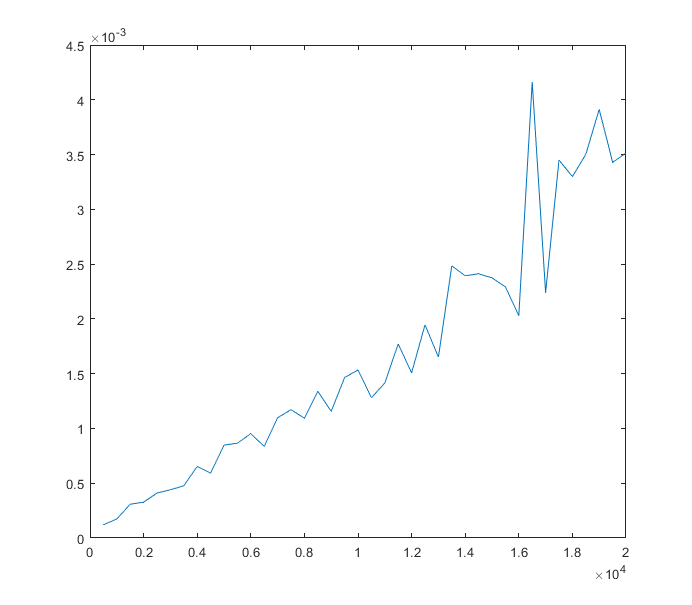

m = 500:500:20000;
for k = 1:numel(m)
    f = @() sinfun1(m(k));
    t(k) = timeit(f);
end
plot(m,t)

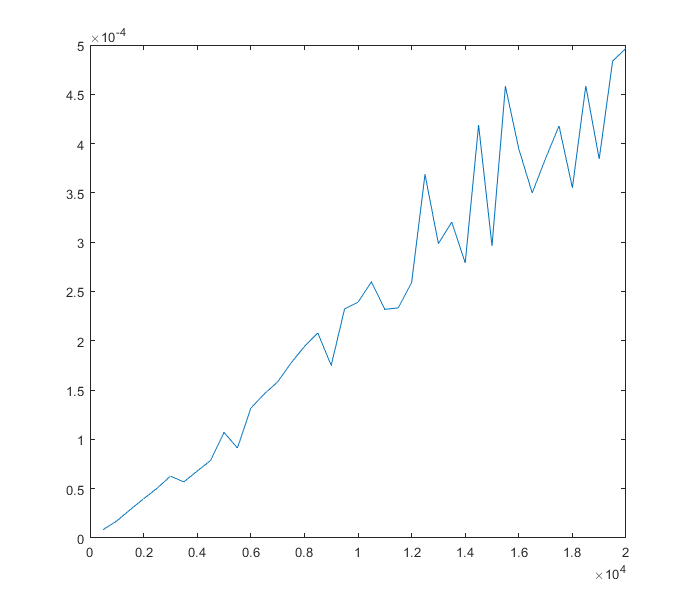

m = 500:500:20000;
for k = 1:numel(m)
    f = @() sinfun2(m(k));
    t(k) = timeit(f);
end
plot(m,t)

timeit(@() sinfun1(20000))

ans = 0.0033

timeit(@() sinfun2(20000))

ans = 4.0590e-04

timeit(@() sinfun3(20000))

ans = 5.8660e-04

timeit(@() twodsin1(1,1/(4*pi),1/(4*pi),512,512))

ans = 0.0075

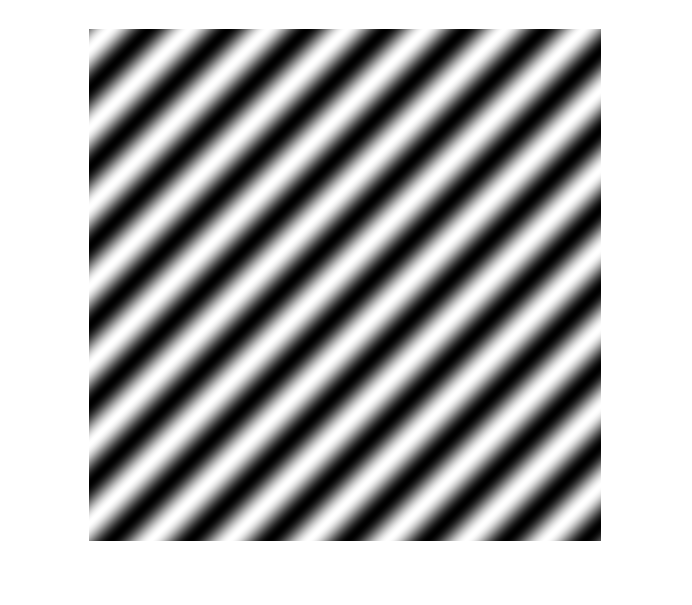

f = twodsin1(1,1/(4*pi),1/(4*pi),512,512);
imshow(f,[])

timeit(@() twodsin2(1,1/(4*pi),1/(4*pi),512,512))

ans = 0.0054